# Practico con utilitario 1

Se tiene una señal discreta y finita $x\left\lbrack \;n\right\rbrack$

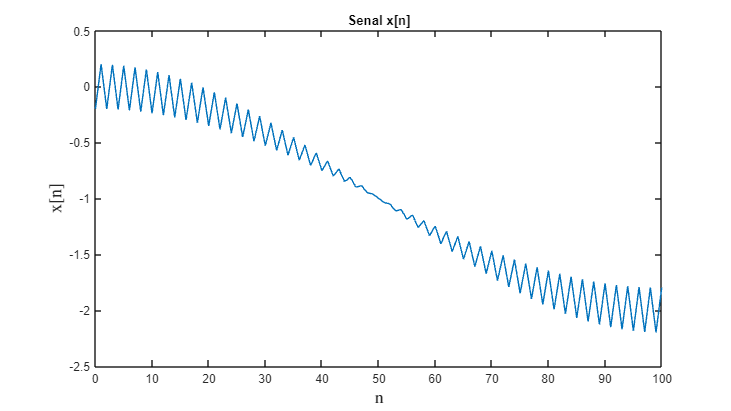

[n,xn] = senial(748695);

plotCompleto(n,xn,title="Senal x[n]",xlabel="n",ylabel="x[n]")

La señal parece estar compuesta por dos ondas, una de baja frecuencia con mayor amplitud y una de alta frecuencia y menor amplitud, ademas de un offset en continua de -1.

La señal de baja frecuencia parece completar medio periodo en una duracion de 100 muestras, por lo que se puede suponer que su periodo es $T=\;200$, y por lo tanto su frecuencia es $s=\frac{1}{T}=\frac{1}{200}$. Tambien se puede ver que oscila entre 0 y -2 por lo que tiene una amplitud de 1

Grafico solo las 10 primeras muestras de la señal para poder ver la onda de alta frecuencia con mayor detalle 

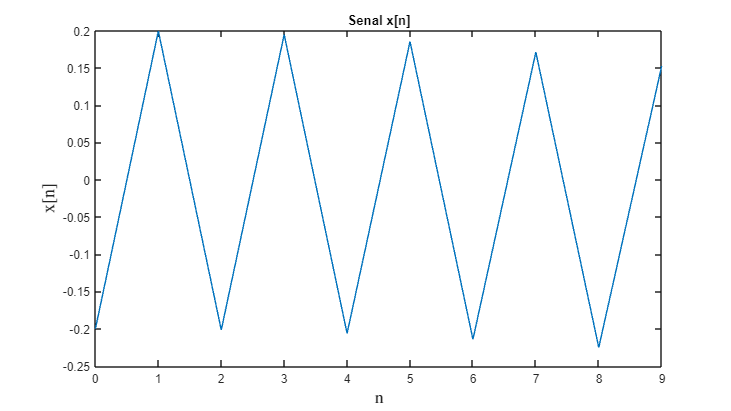

plotCompleto(n(1:10),xn(1:10),title="Senal x[n]",xlabel="n",ylabel="x[n]")

La onda de alta frecuencia tiene un periodo $T=2$ y por lo tanto una frecuencia $\;s=\frac{1}{T}=\frac{1}{2}$. Se puede ver que la onda oscila entre -0.2 y 0.2, por lo que su amplitud es de 1/5

El offset de -1 obviamente tiene una frecuencia $s=0$

Lo que esperaria ver en la TFTD son tres deltas, en los valores de frecuencia $s=0$, $s=\frac{1}{200}$ y $s=\frac{1}{2}$

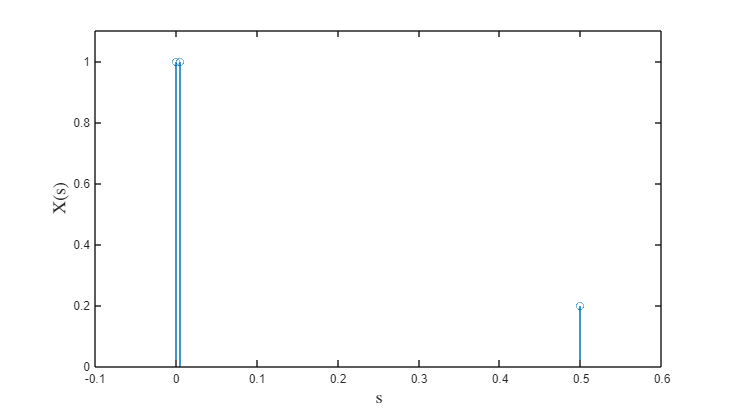

stemCompleto([0,0.005,0.5],[1,1,0.2],xlabel="s",ylabel="X(s)")
xlim([-0.1,0.6])
ylim([0,1.1])

Devido a que x[n] es una señal de soporte finito, la **TFTD** que puedo calcular no es la de la señal que va de menos infinito a infinito, si no la de la señal por un cajon de soporte 101, que es la cantidad de muestras con la que cuenta la señal. Debido a esto, la tranformada no van a ser tres deltas, sino tres sincs centradas en estas deltas

## Tranformada de Fourier de la señal de tiempo discreto (TFTD)

La TFTD de una señal de soporte finito, se puede calcular como:

    
$$X\left(s\right)=\sum_{n=0}^k x\left\lbrack n\right\rbrack \times e^{-\textrm{j2}\pi \textrm{sn}}$$


donde ***k*** es el numero de muestras de la señal y ***s ***es la frecuencia normalizada.

$X\left(s\right)$ es una funcion periodica de periodo 1, por lo que solo la voy a graficar entre $s=-\frac{1}{2}$ y $s=\frac{1}{2}$  ya que mas allá de eso seria redundante. Tambien como ***s*** es una variable continua, para calcular la** TFTD** numericamente voy a usar valores discretos de ***s*** con un paso $\textrm{ds}=0\ldotp 0001$ 

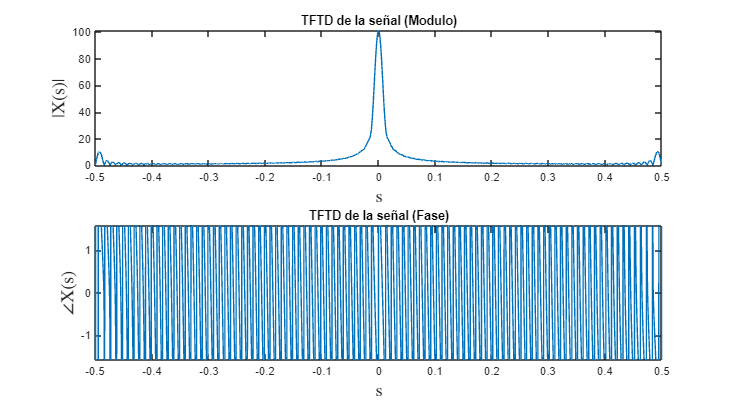

ds = 0.0001; s = -0.5:ds:0.5;
Xs = TFTD(xn,[-0.5 0.5],ds);

plotsCompletos(s,abs(Xs),angle(Xs),title1="TFTD de la señal (Modulo)",xlabel="s",ylabel1="|X(s)|",title2="TFTD de la señal (Fase)",ylabel2="\angle X(s)")

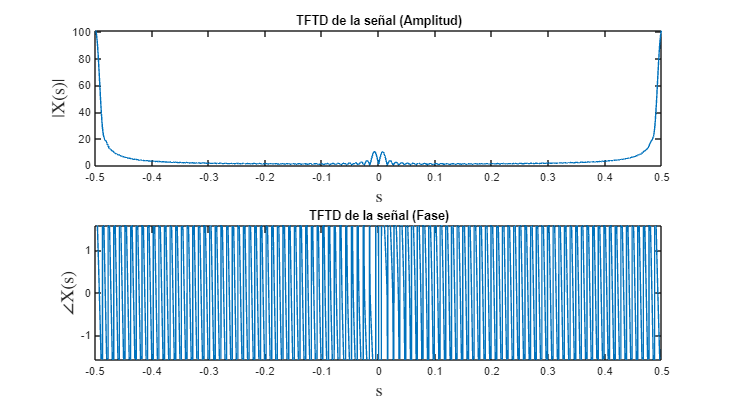

plotsCompletos(s,abs(fft(xn,length(s))),angle(fft(xn,length(s))),title1="TFTD de la señal (Amplitud)",xlabel="s",ylabel1="|X(s)|",title2="TFTD de la señal (Fase)",ylabel2="\angle X(s)")

Antes predije tres sinc para tres frecuencias distintas, pero en el grafico solo se llegan a apreciar un pico en torno a $s=0$ y otro en torno a $s=\frac{1}{2}$. La razon de esta discrepancia probablemente sea porque que no tengo suficiente resolucion en frecuencia como para dicernir entre la sinc centrada en $s=0$ y la sinc centrada en $s=\frac{1}{200}$. Para poder dicernir entre ambas frecuencias necesitaria una mayor duracion de la señal, es decir un mayor numero de muestras.

## Sistemas descritos por ecuaciones de diferencias 

Se tienen cuatro señales descritas por las siguientes ecuaciones en diferencias:


$$y_1 \left\lbrack n\right\rbrack \;=\frac{1}{2}x\left\lbrack n\right\rbrack +\frac{1}{2}x\left\lbrack n-1\right\rbrack$$



$$y_2 \left\lbrack n\right\rbrack =\frac{1}{2}x\left\lbrack n\right\rbrack -\frac{1}{2}x\left\lbrack n-1\right\rbrack$$



$$y_3 \left\lbrack n\right\rbrack =\frac{1}{4}x\left\lbrack n\right\rbrack +\frac{1}{4}x\left\lbrack n-1\right\rbrack +\frac{1}{2}y_3 \left\lbrack n-1\right\rbrack$$



$$y_4 \left\lbrack n\right\rbrack =\frac{1}{4}x\left\lbrack n\right\rbrack +\frac{1}{4}x\left\lbrack n-1\right\rbrack -\frac{1}{2}y_4 \left\lbrack n-1\right\rbrack$$


### Respuesta en frecuencia de los sistemas

un sistema lineal e independiente en el tiempo puede caracterisarse a partir de su respuesta al impulso a partir de la siguiente ecuacion:

$y\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack$, 

Transformando la ecuacion anterior se optiene:

$Y\left(s\right)=H\left(s\right)\times X\left(s\right)$, 

por lo tanto

 
$$H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}$$


$H\left(s\right)$ tambien puede obtenerse como la ***TFTD*** de $h\left\lbrack n\right\rbrack$, siendo $h\left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack$ cuando $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$. Graficare la respuesta en frecuencia obtenida por ambos metodos para compararlas.

#### Sistema 1


$$Y_1 \left(s\right)=\frac{1}{2}X\left(s\right)+\frac{1}{2}X\left(s\right)\times e^{-\textrm{j2}\pi s\;}$$



$$\begin{array}{l}
Y_1 \left(s\right)=\frac{1}{2}X\left(s\right)\times \left(1+e^{-\textrm{j2}\pi s} \right)\\
H_1 \left(s\right)=\frac{Y_1 \left(s\right)}{X\left(s\right)}=\frac{1}{2}\left(1+e^{-\textrm{j2}\pi s} \right)
\end{array}$$


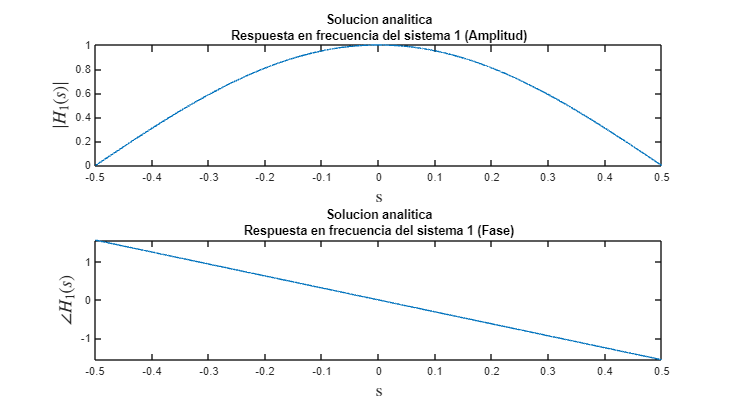

Hs_1a = 0.5 + 0.5*exp(-1j*2*pi*s); %Expresion analitica
Hs_1n = TFTD(y1(delta_kronecker(n)),[-0.5 0.5], 0.0001); %Calculo numerico

plotsCompletos(s,abs(Hs_1a),angle(Hs_1a),title1={"Solucion analitica","Respuesta en frecuencia del sistema 1 (Amplitud)"},xlabel="s",ylabel1="$|H_1(s)|$",title2={"Solucion analitica","Respuesta en frecuencia del sistema 1 (Fase)"},ylabel2="$\angle H_1(s)$")

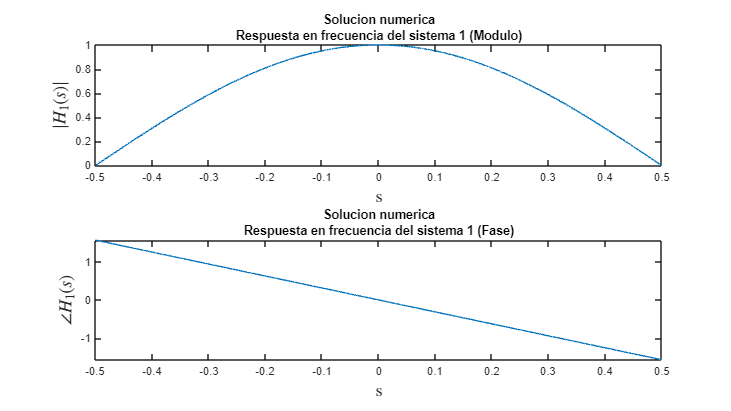

plotsCompletos(s,abs(Hs_1n),angle(Hs_1n),title1={"Solucion numerica","Respuesta en frecuencia del sistema 1 (Modulo)"},xlabel="s",ylabel1="$|H_1(s)|$",title2={"Solucion numerica","Respuesta en frecuencia del sistema 1 (Fase)"},ylabel2="$\angle H_1(s)$")

La respuesta en frecuencia del sistema 1 es la de un filtro pasa bajos

#### Sistema 2


$$Y_2 \left(s\right)=\frac{1}{2}X\left(s\right)-\frac{1}{2}X\left(s\right)\times e^{-\textrm{j2}\pi s}$$



$$\begin{array}{l}
Y_2 \left(s\right)=\frac{1}{2}X\left(s\right)\times \left(1-e^{-\textrm{j2}\pi s} \right)\\
H_2 \left(s\right)=\frac{Y_2 \left(s\right)}{X\left(s\right)}=\frac{1}{2}\left(1-e^{-\textrm{j2}\pi s} \right)
\end{array}$$


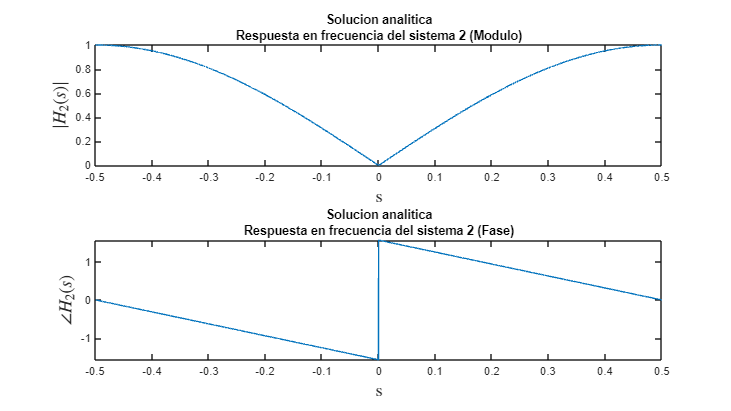

Hs_2a = 0.5 - 0.5*exp(-1j*2*pi*s); %Expresion analitica
Hs_2n = TFTD(y2(delta_kronecker(n)),[-0.5 0.5], 0.0001); %Calculo numerico

plotsCompletos(s,abs(Hs_2a),angle(Hs_2a),title1={"Solucion analitica","Respuesta en frecuencia del sistema 2 (Modulo)"},xlabel="s",ylabel1="$|H_2(s)|$",title2={"Solucion analitica","Respuesta en frecuencia del sistema 2 (Fase)"},ylabel2="$\angle H_2(s)$")

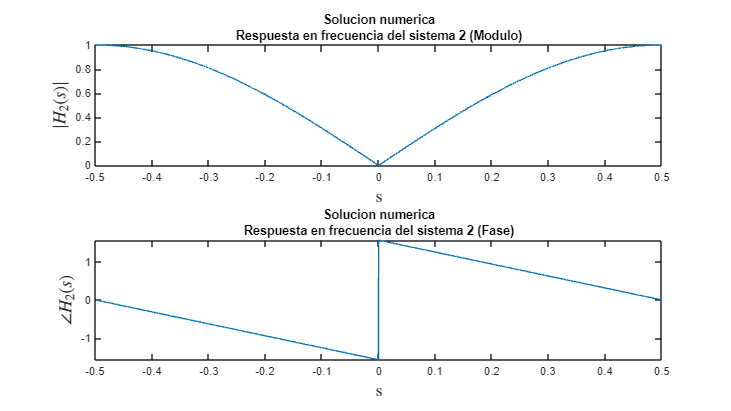

plotsCompletos(s,abs(Hs_2n),angle(Hs_2n),title1={"Solucion numerica","Respuesta en frecuencia del sistema 2 (Modulo)"},xlabel="s",ylabel1="$|H_2(s)|$",title2={"Solucion numerica","Respuesta en frecuencia del sistema 2 (Fase)"},ylabel2="$\angle H_2(s)$")

La respuesta en frecuencia del sistema 2 es la de un filtro pasa altos.

#### Sistema 3


$$\begin{array}{l}
Y_3 \left(s\right)=\frac{1}{4}X\left(s\right)+\frac{1}{4}X\left(s\right)\times e^{-\textrm{j2}\pi s} +\frac{1}{2}Y_3 \left(s\right)\times e^{-\textrm{j2}\pi s} \\
Y_3 \left(s\right)-\frac{1}{2}Y_3 \left(s\right)\times e^{-\textrm{j2}\pi s} =\frac{1}{4}X\left(s\right)+\frac{1}{4}X\left(s\right)\times e^{-\textrm{j2}\pi s} \;\\
Y_3 \left(s\right)\times \left(1-\frac{1}{2}e^{-\textrm{j2}\pi s} \right)=\frac{1}{4}X\left(s\right)\times \left(1+e^{-\textrm{j2}\pi s} \right)\\
Y_3 \left(s\right)=\frac{1}{4}X\left(s\right)\times \left(1+e^{-\textrm{j2}\pi s} \right)\times \frac{1}{\left(1-\frac{1}{2}e^{-\textrm{j2}\pi s} \right)}\\
H_3 \left(s\right)=\frac{Y_3 \left(s\right)}{X\left(s\right)}=\frac{1}{4}\left(1+e^{-\textrm{j2}\pi s} \right)\times \frac{1}{\left(1-\frac{1}{2}e^{-\textrm{j2}\pi s} \right)}
\end{array}$$


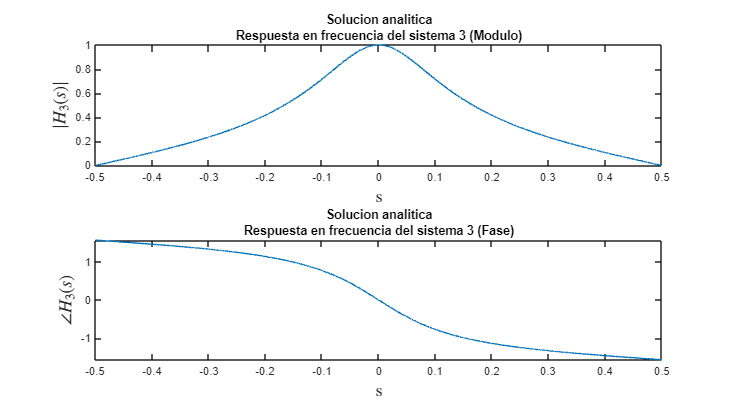

Hs_3a = (0.25 + 0.25*(exp(-1j*2*pi*s)))./(1 - 0.5*exp(-1j*2*pi*s)); %Expresion analitica
Hs_3n = TFTD(y3(delta_kronecker(n)),[-0.5 0.5], 0.0001); %Calculo numerico

plotsCompletos(s,abs(Hs_3a),angle(Hs_3a),title1={"Solucion analitica","Respuesta en frecuencia del sistema 3 (Modulo)"},xlabel="s",ylabel1="$|H_3(s)|$",title2={"Solucion analitica","Respuesta en frecuencia del sistema 3 (Fase)"},ylabel2="$\angle H_3(s)$")

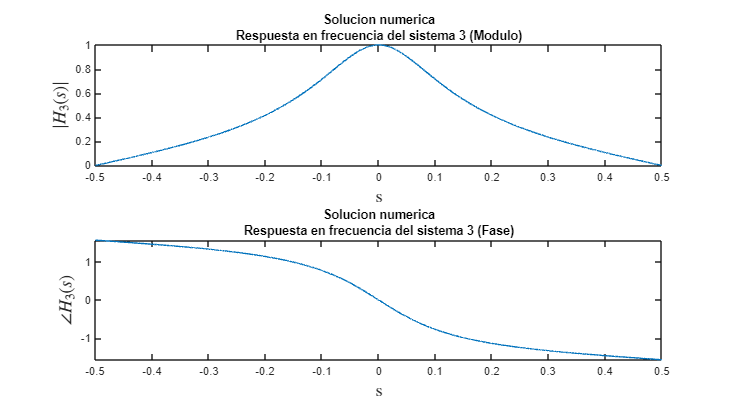

plotsCompletos(s,abs(Hs_3n),angle(Hs_3n),title1={"Solucion numerica","Respuesta en frecuencia del sistema 3 (Modulo)"},xlabel="s",ylabel1="$|H_3(s)|$",title2={"Solucion numerica","Respuesta en frecuencia del sistema 3 (Fase)"},ylabel2="$\angle H_3(s)$")

La respuesta en frecuencia del sistema 3 es la de un filtro pasa bajos, con una caida de la amplitud con la frecuencia mas abrupta que el sistema 1.

#### Sistema 4


$$\begin{array}{l}
Y_4 \left(s\right)=\frac{1}{4}X\left(s\right)-\frac{1}{4}X\left(s\right)\times e^{-\textrm{j2}\pi s} -\frac{1}{2}Y_4 \left(s\right)\times e^{-\textrm{j2}\pi s} \\
Y_4 \left(s\right)+\frac{1}{2}Y_4 \left(s\right)\times e^{-\textrm{j2}\pi s} =\frac{1}{4}X\left(s\right)-\frac{1}{4}X\left(s\right)\times e^{-\textrm{j2}\pi s} \;\\
Y_4 \left(s\right)\times \left(1+\frac{1}{2}e^{-\textrm{j2}\pi s} \right)=\frac{1}{4}X\left(s\right)\times \left(1-e^{-\textrm{j2}\pi s} \right)\\
Y_4 \left(s\right)=\frac{1}{4}X\left(s\right)\times \left(1-e^{-\textrm{j2}\pi s} \right)\times \frac{1}{\left(1+\frac{1}{2}e^{-\textrm{j2}\pi s} \right)}\\
H_4 \left(s\right)=\frac{Y_4 \left(s\right)}{X\left(s\right)}=\frac{1}{4}\left(1-e^{-\textrm{j2}\pi s} \right)\times \frac{1}{\left(1+\frac{1}{2}e^{-\textrm{j2}\pi s} \right)}
\end{array}$$


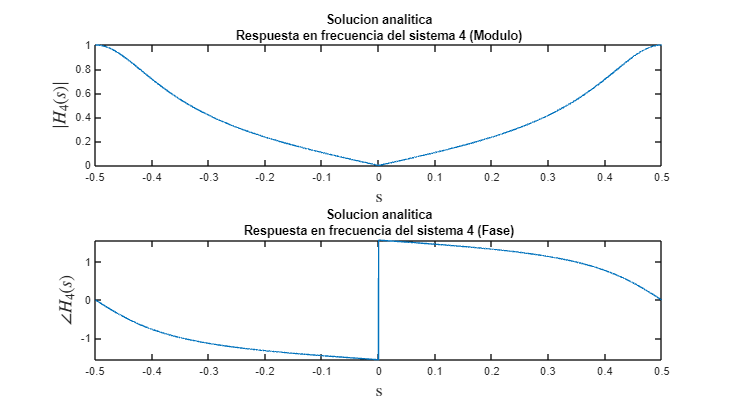

Hs_4a = (0.25 - 0.25*(exp(-1j*2*pi*s)))./(1 + 0.5*exp(-1j*2*pi*s)); %Expresion analitica
Hs_4n = TFTD(y4(delta_kronecker(n)),[-0.5 0.5], 0.0001); %Calculo numerico

plotsCompletos(s,abs(Hs_4a),angle(Hs_4a),title1={"Solucion analitica","Respuesta en frecuencia del sistema 4 (Modulo)"},xlabel="s",ylabel1="$|H_4(s)|$",title2={"Solucion analitica","Respuesta en frecuencia del sistema 4 (Fase)"},ylabel2="$\angle H_4(s)$")

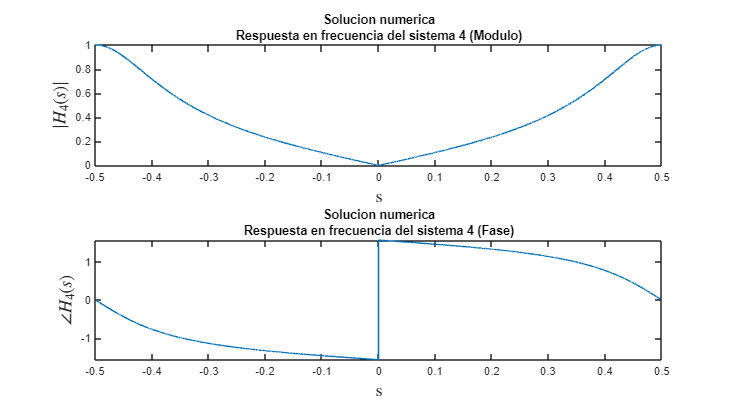

plotsCompletos(s,abs(Hs_4n),angle(Hs_4n),title1={"Solucion numerica","Respuesta en frecuencia del sistema 4 (Modulo)"},xlabel="s",ylabel1="$|H_4(s)|$",title2={"Solucion numerica","Respuesta en frecuencia del sistema 4 (Fase)"},ylabel2="$\angle H_4(s)$")

La respuesta en frecuencia del sistema 4 es la de un filtro pasa altos, con una caida de la amplitud con la inversa de la frecuencia mas abrupta que el sistema 2.

Se puede ver claramente que los graficos son los mismos independientemente de la forma de calcular $H\left(s\right)$, lo cual es el resultado esperado.

### Respuesta al impulso 

Antitransformando $H\left(s\right)$ obtengo $h\left\lbrack n\right\rbrack$. Tambien puedo obtener $h\left\lbrack n\right\rbrack$ calculando la $y\left\lbrack n\right\rbrack$ cuando $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$.

Graficare los resultados de ambos metodos para compararlos.

#### Sistema 1


$$\begin{array}{l}
H_1 \left(s\right)=\frac{1}{2}+\frac{1}{2}e^{-\textrm{j2}\pi s} \\
h_1 \left\lbrack n\right\rbrack =\frac{1}{2}\delta \left\lbrack n\right\rbrack +\frac{1}{2}\delta \left\lbrack n-1\right\rbrack 
\end{array}$$


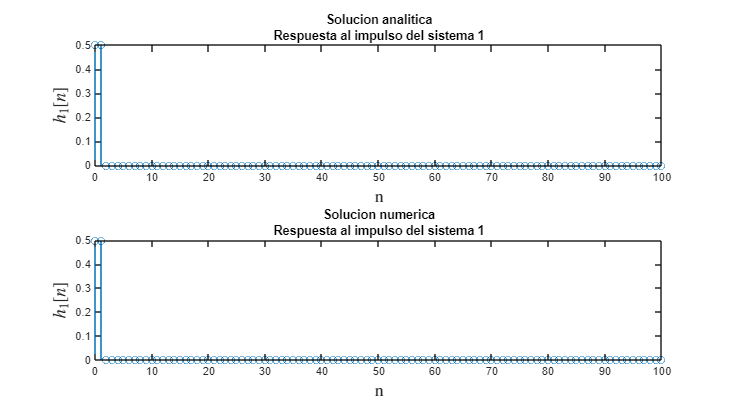

hn_1 = 0.5*delta_kronecker(n) + 0.5*delta_kronecker(n-1);

stemsCompletos(n,hn_1,y1(delta_kronecker(n)),title1={"Solucion analitica","Respuesta al impulso del sistema 1"},xlabel="n",ylabel1="$h_1[n]$",title2={"Solucion numerica","Respuesta al impulso del sistema 1"},ylabel2="$h_1[n]$")

#### Sistema 2


$$\begin{array}{l}
H_2 \left(s\right)=\frac{1}{2}-\frac{1}{2}e^{-\textrm{j2}\pi s} \\
h_1 \left\lbrack n\right\rbrack =\frac{1}{2}\delta \left\lbrack n\right\rbrack -\frac{1}{2}\delta \left\lbrack n-1\right\rbrack 
\end{array}$$


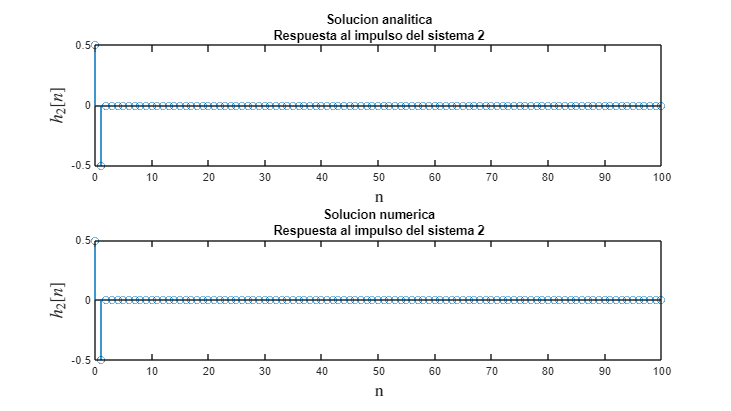

hn_2 = 0.5*delta_kronecker(n) - 0.5*delta_kronecker(n-1);

stemsCompletos(n,hn_2,y2(delta_kronecker(n)),title1={"Solucion analitica","Respuesta al impulso del sistema 2"},xlabel="n",ylabel1="$h_2[n]$",title2={"Solucion numerica","Respuesta al impulso del sistema 2"},ylabel2="$h_2[n]$")

#### Sistema 3


$$\begin{array}{l}
H_3 \left(s\right)=\left(\frac{1}{4}+\frac{1}{4}e^{-\textrm{j2}\pi s} \right)\times \frac{1}{1-\frac{1}{2}e^{-\textrm{j2}\pi s} }\\
h_3 \left\lbrack n\right\rbrack =\left(\frac{1}{4}\delta \left\lbrack n\right\rbrack *U\left\lbrack n\right\rbrack \times \frac{1}{2^n }\right)+\left(\frac{1}{4}\delta \left\lbrack n-1\right\rbrack *U\left\lbrack n\right\rbrack \times \frac{1}{2^n }\right)\\
h_3 \left\lbrack n\right\rbrack =\frac{1}{4}\times \frac{1}{2^n }\times U\left\lbrack n\right\rbrack +\frac{1}{4}\times \frac{1}{2^{n-1} }\times U\left\lbrack n-1\right\rbrack 
\end{array}$$


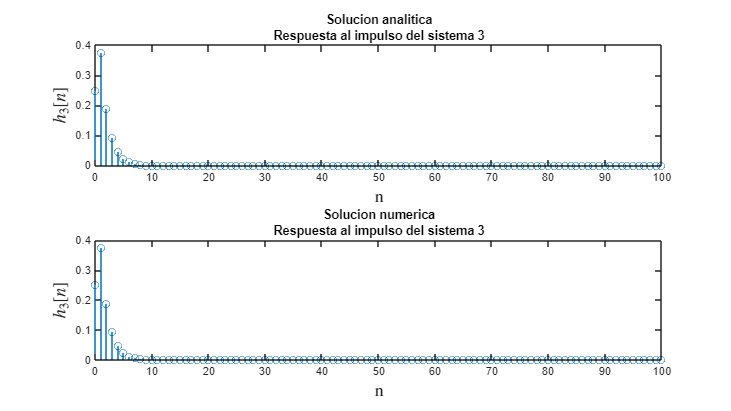

hn_3 = (0.25*0.5.^n).*escalon(n) + (0.25*0.5.^(n-1)).*escalon(n-1);

stemsCompletos(n,hn_3,y3(delta_kronecker(n)),title1={"Solucion analitica","Respuesta al impulso del sistema 3"},xlabel="n",ylabel1="$h_3[n]$",title2={"Solucion numerica","Respuesta al impulso del sistema 3"},ylabel2="$h_3[n]$")

#### Sistema 4


$$\begin{array}{l}
H_4 \left(s\right)=\left(\frac{1}{4}-\frac{1}{4}e^{-\textrm{j2}\pi s} \right)\times \frac{1}{1+\frac{1}{2}e^{-\textrm{j2}\pi s} }\\
h_3 \left\lbrack n\right\rbrack =\left(\frac{1}{4}\delta \left\lbrack n\right\rbrack *U\left\lbrack n\right\rbrack \times {\left(-\frac{1}{2}\right)}^n \right)-\left(\frac{1}{4}\delta \left\lbrack n-1\right\rbrack *U\left\lbrack n\right\rbrack \times {\left(-\frac{1}{2}\right)}^n \right)\\
h_3 \left\lbrack n\right\rbrack =\frac{1}{4}\times {\left(-\frac{1}{2}\right)}^n \times U\left\lbrack n\right\rbrack -\frac{1}{4}\times {\left(-\frac{1}{2}\right)}^{n-1} \times U\left\lbrack n-1\right\rbrack 
\end{array}$$


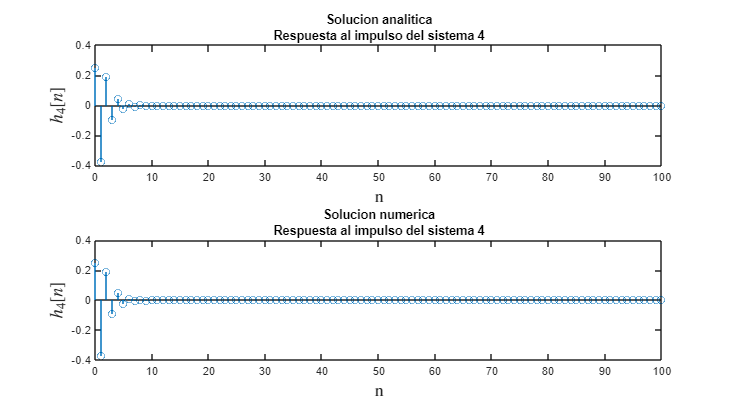

hn_4 = (0.25*(-0.5).^n).*escalon(n) - (0.25*(-0.5).^(n-1)).*escalon(n-1);

stemsCompletos(n,hn_4,y4(delta_kronecker(n)),title1={"Solucion analitica","Respuesta al impulso del sistema 4"},xlabel="n",ylabel1="$h_4[n]$",title2={"Solucion numerica","Respuesta al impulso del sistema 4"},ylabel2="$h_4[n]$")

## Señales de salida de los sistemas

se pasara la señal $x\left\lbrack n\right\rbrack$ obtenida de la funcion senial.m por los cuatro sistemas y se graficara la señal de salida 

Las respuestas en frecuencia para las frecuencias $s=0$ y $s=\frac{1}{2}$ son iguales para los sistemas $y_1 \left\lbrack n\right\rbrack$ y $y_3 \left\lbrack n\right\rbrack$ y para los sistemas $y_2 \left\lbrack n\right\rbrack$ y $y_4 \left\lbrack n\right\rbrack$.

La señal de entrada solo tiene contenido frecuencial en torno a $s=0$ y $s=\frac{1}{2}$ por lo que es de esperar que la salida de los sistemas sean practicamente iguales entre los sistemas $y_1 \left\lbrack n\right\rbrack$ y $y_3 \left\lbrack n\right\rbrack$ y los sistemas $y_2 \left\lbrack n\right\rbrack$ y $y_4 \left\lbrack n\right\rbrack$

#### sistema 1

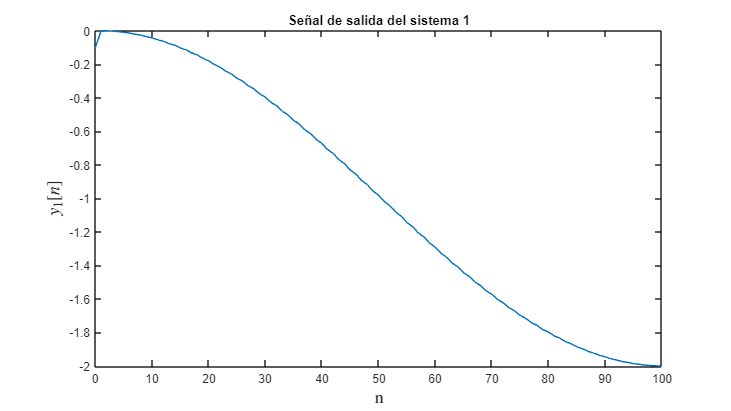

plotCompleto(n,y1(xn),title="Señal de salida del sistema 1",xlabel="n",ylabel="$y_1[n]$")

#### sistema 2

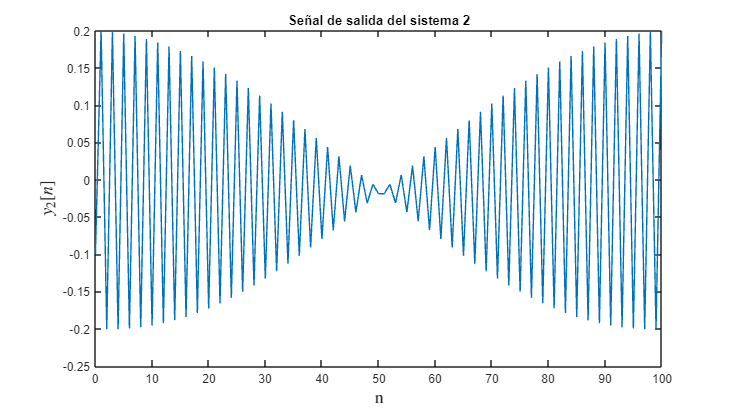

plotCompleto(n,y2(xn),title="Señal de salida del sistema 2",xlabel="n",ylabel="$y_2[n]$")

#### sistema 3

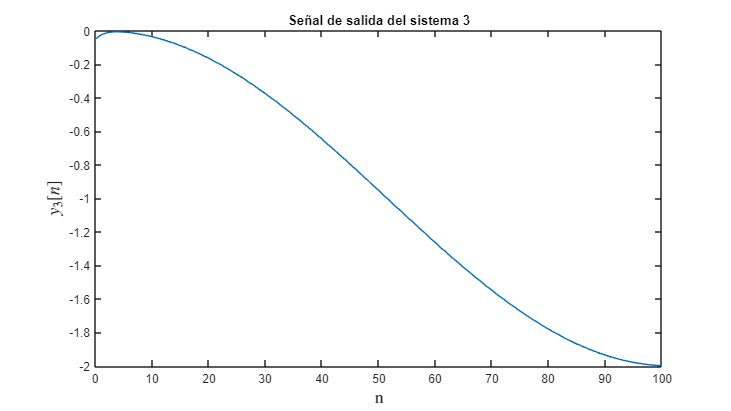

plotCompleto(n,y3(xn),title="Señal de salida del sistema 3",xlabel="n",ylabel="$y_3[n]$")

#### sistema 4

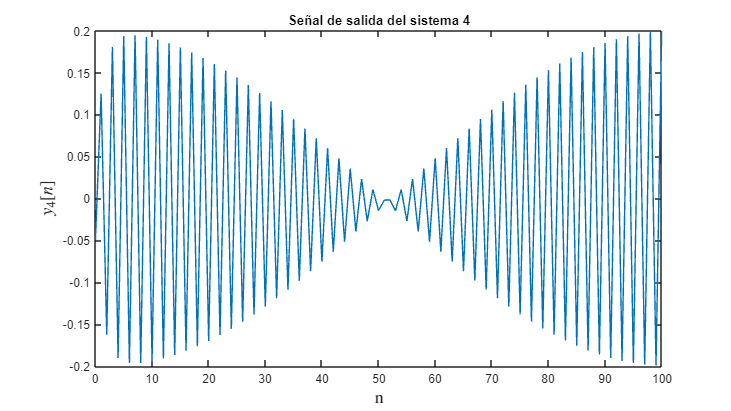

plotCompleto(n,y4(xn),title="Señal de salida del sistema 4",xlabel="n",ylabel="$y_4[n]$")

## TFTD de las señales de salida

Grafico las TFTDs de las señales se salida calculadas anteriormente

#### sistema 1

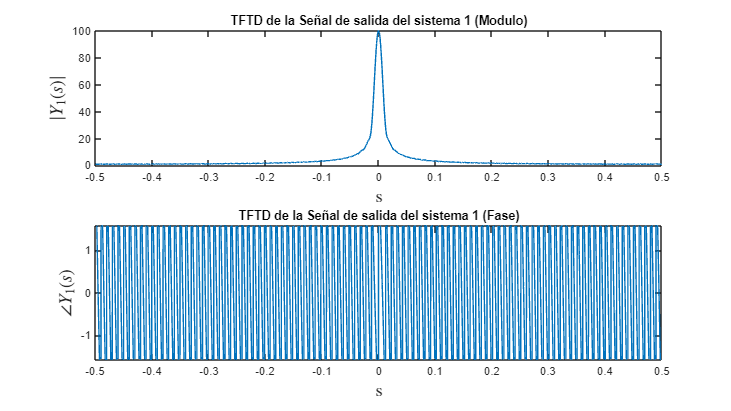

plotsCompletos(s,abs(TFTD(y1(xn),[-0.5 0.5],ds)),angle(TFTD(y1(xn),[-0.5 0.5],ds)),title1="TFTD de la Señal de salida del sistema 1 (Modulo)",xlabel="s",ylabel1="$|Y_1(s)|$",title2="TFTD de la Señal de salida del sistema 1 (Fase)",ylabel2="$\angle Y_1(s)$")

El sistema $y_1 \left\lbrack n\right\rbrack$ es un filtro pasa bajos, por lo que permanece el contenido en las frecuencias $s=0$ y $s=\frac{1}{200}$, pero se atenuo practicamente por completo el contenido en frecuencia $s=\frac{1}{2}$

#### sistema 2

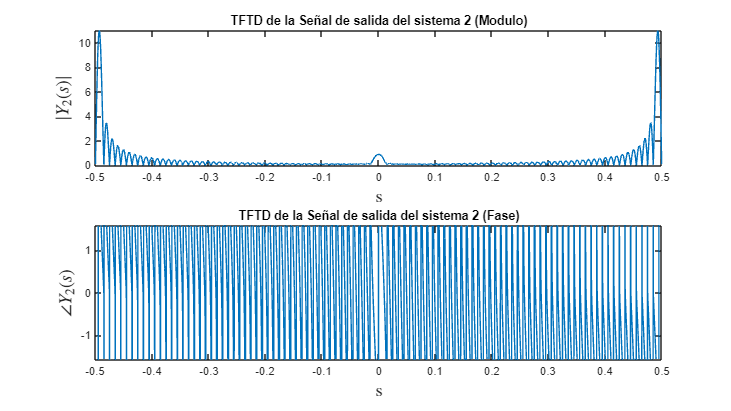

plotsCompletos(s,abs(TFTD(y2(xn),[-0.5 0.5],ds)),angle(TFTD(y2(xn),[-0.5 0.5],ds)),title1="TFTD de la Señal de salida del sistema 2 (Modulo)",xlabel="s",ylabel1="$|Y_2(s)|$",title2="TFTD de la Señal de salida del sistema 2 (Fase)",ylabel2="$\angle Y_2(s)$")

El sistema $y_2 \left\lbrack n\right\rbrack$ es un sistema pasa altos, por lo que permanece el contenido en las frecuencias $s=\frac{1}{2}$ , pero se atenua practicamente por completo el contenido en frecuencia $s=0$ y $s=\frac{1}{200}$

#### sistema 3

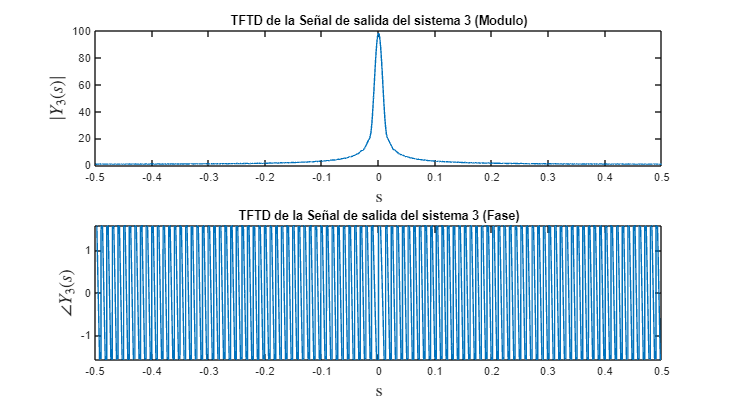

plotsCompletos(s,abs(TFTD(y3(xn),[-0.5 0.5],ds)),angle(TFTD(y3(xn),[-0.5 0.5],ds)),title1="TFTD de la Señal de salida del sistema 3 (Modulo)",xlabel="s",ylabel1="$|Y_3(s)|$",title2="TFTD de la Señal de salida del sistema 3 (Fase)",ylabel2="$\angle Y_3(s)$")

El sistema $y_3 \left\lbrack n\right\rbrack$ es un filtro pasa bajos, por lo que permanece el contenido en las frecuencias $s=0$ y $s=\frac{1}{200}$, pero se atenuo practicamente por completo el contenido en frecuencia $s=\frac{1}{2}$

#### sistema 4

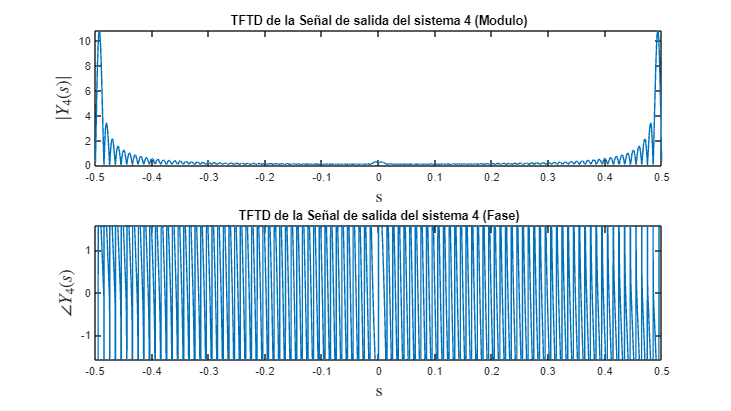

plotsCompletos(s,abs(TFTD(y4(xn),[-0.5 0.5],ds)),angle(TFTD(y4(xn),[-0.5 0.5],ds)),title1="TFTD de la Señal de salida del sistema 4 (Modulo)",xlabel="s",ylabel1="$|Y_4(s)|$",title2="TFTD de la Señal de salida del sistema 4 (Fase)",ylabel2="$\angle Y_4(s)$")

El sistema $y_4 \left\lbrack n\right\rbrack$ es un sistema pasa altos, por lo que permanece el contenido en las frecuencias $s=\frac{1}{2}$ , pero se atenua practicamente por completo el contenido en frecuencia $s=0$ y $s=\frac{1}{200}$

## Canal digital con dos ecos

#### Respuesta al impulso del canal

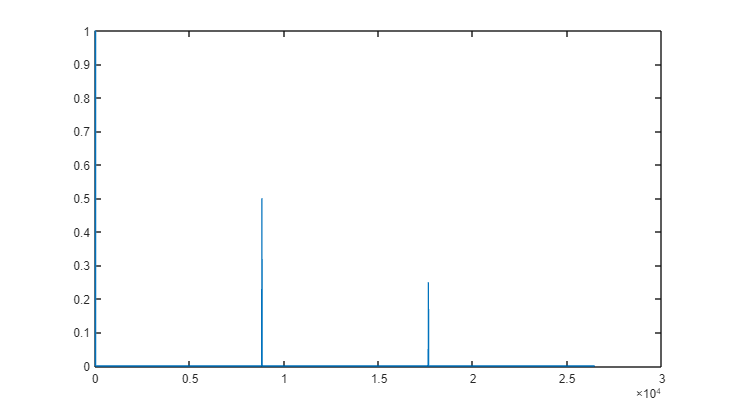

[n_A,hn_A] = hcanald(748695);
plotCompleto(n_A,hn_A)

find(hn_A)

ans =            1        8821       17641


function Xs = TFTD(x,lim,ds)
    arguments
        x   (1,:) {mustBeNumeric}
        lim (1,2) {mustBeNumeric}
        ds  (1,1) {mustBeNumeric}
    end
    s = lim(1):ds:lim(2); 
    Xs = zeros(1,length(s));
    n = 0:length(x)-1;
    for i = 1:length(Xs)
        Xs(i) = sum(x.*exp(-1j*2*pi*s(i).*n));
    end
end

function y = y1(x) 
    arguments
        x (1,:) {mustBeNumeric}
    end
    y = zeros(1,length(x));
    % Asumo que X[-1] = 0, por lo que y[0] = 0.5*X[0]
    y(1) = 0.5*x(1);
    for n = 2:length(x)
        y(n) = 0.5*x(n) + 0.5*x(n-1);
    end
end

function y = y2(x)
    arguments
        x (1,:) {mustBeNumeric}
    end
    y = zeros(1,length(x));
    % Asumo que X[-1] = 0, por lo que y[0] = 0.5*X[0]
    y(1) = 0.5*x(1);
    for n = 2:length(x)
        y(n) = 0.5*x(n) - 0.5*x(n-1);
    end
end

function y = y3(x)
    arguments
        x (1,:) {mustBeNumeric}
    end
    y = zeros(1,length(x));
    % Asumo que X[-1] = 0 y y[-1] = 0, por lo que y[0] = 0.25*X[0]
    y(1) = 0.25*x(1);
    for n = 2:length(x)
        y(n) = 0.25*x(n) + 0.25*x(n-1) + 0.5*y(n-1);
    end
end

function y = y4(x)
    arguments
        x (1,:) {mustBeNumeric}
    end
    y = zeros(1,length(x));
    % Asumo que X[-1] = 0 y y[-1] = 0, por lo que y[0] = 0.25*X[0]
    y(1) = 0.25*x(1);
    for n = 2:length(x)
        y(n) = 0.25*x(n) - 0.25*x(n-1) - 0.5*y(n-1);
    end
end

function delta = delta_kronecker(n)
    arguments(Input)
        n (1,:) {mustBeNumeric}
    end
    arguments(Output)
        delta (1,:) double
    end
    delta = (n == 0);
end

function u = escalon(n)
    arguments(Input)
        n (1,:) {mustBeNumeric}
    end
    arguments(Output)
        u (1,:) double
    end
    u = (n >= 0);
end

function stemsCompletos(X,Y1,Y2,options)
    arguments
        X  (1,:) {mustBeNumeric}
        Y1 (1,:) {mustBeNumeric}
        Y2 (1,:) {mustBeNumeric}
        options.title1  (1,:) string = ""
        options.title2  (1,:) string = ""
        options.xlabel  (1,:) string = ""
        options.ylabel1 (1,:) string = ""
        options.ylabel2 (1,:) string = ""
    end

    figure(Units = "normalized",OuterPosition = [0 0 0.6 0.6])
    subplot(2,1,1)
    stem(X,Y1)
    title(options.title1)
    xlabel(options.xlabel,Interpreter='latex',FontSize=15)
    ylabel(options.ylabel1,Interpreter='latex',FontSize=15)
    
    subplot(2,1,2)
    stem(X,Y2)
    title(options.title2)
    xlabel(options.xlabel,Interpreter='latex',FontSize=15)
    ylabel(options.ylabel2,Interpreter='latex',FontSize=15)
end

function plotsCompletos(X,Y1,Y2,options)
    arguments
        X  (1,:) {mustBeNumeric}
        Y1 (1,:) {mustBeNumeric}
        Y2 (1,:) {mustBeNumeric}
        options.title1  (1,:) string = ""
        options.title2  (1,:) string = ""
        options.xlabel  (1,:) string = ""
        options.ylabel1 (1,:) string = ""
        options.ylabel2 (1,:) string = ""
    end
    
    figure(Units = "normalized",OuterPosition = [0 0 0.6 0.6])
    subplot(2,1,1)
    plot(X,Y1)
    title(options.title1)
    xlabel(options.xlabel,Interpreter='latex',FontSize=15)
    ylabel(options.ylabel1,Interpreter='latex',FontSize=15)
    
    subplot(2,1,2)
    plot(X,Y2)
    title(options.title2)
    xlabel(options.xlabel,Interpreter='latex',FontSize=15)
    ylabel(options.ylabel2,Interpreter='latex',FontSize=15)
    ylim([-pi/2,pi/2])
end

function stemCompleto(X,Y,options)
    arguments
        X (1,:) {mustBeNumeric}
        Y (1,:) {mustBeNumeric}
        options.title  (1,:) string = ""
        options.xlabel  (1,:) string = ""
        options.ylabel (1,:) string = ""
    end

    figure(Units = "normalized",OuterPosition = [0 0 0.6 0.6])
    stem(X,Y)
    title(options.title)
    xlabel(options.xlabel,Interpreter='latex',FontSize=15)
    ylabel(options.ylabel,Interpreter='latex',FontSize=15)

end

function plotCompleto(X,Y,options)
    arguments
        X (1,:) {mustBeNumeric}
        Y (1,:) {mustBeNumeric}
        options.title  (1,:) string = ""
        options.xlabel (1,:) string = ""
        options.ylabel (1,:) string = ""
    end
    
    figure(Units = "normalized",OuterPosition = [0 0 0.6 0.6])
    plot(X,Y)
    title(options.title)
    xlabel(options.xlabel,Interpreter='latex',FontSize=15)
    ylabel(options.ylabel,Interpreter='latex',FontSize=15)

end